TrendTradingMainScript

Preparation

clear
    
tic

Read data

load TrendTrading.mat % IndexTT PriceTTFullRaw VolumeTTFullRaw
% IndexTT ;
% PriceTTFullRaw ;
% VolumesTTFullRaw = VolumeTTFullRaw ;

Clean data

% PricesTTFull = fillmissing (PriceTTFullRaw, "previous") ;
% PricesTTFull = fillmissing (PricesTTFull, "next") ;
% 
% VolumesTTFullRawVars = VolumesTTFullRaw.Variables ;
% VolumesTTFullRawVarsIdx = VolumesTTFullRawVars < 100';
% VolumesTTFullRawVars (VolumesTTFullRawVarsIdx) = NaN ;
% VolumesTTFullRaw.Variables = VolumesTTFullRawVars ;
% VolumesTTFull = fillmissing (VolumesTTFullRaw, "previous") ;


Split dataset into IST and OST

nRowFull = int64 (size (PricesTTFull,1)) ;
nRowISTproportion = 100/100 ;  % Proportion of dataset to be in Sample Dataset
nRowIST = int64(round(nRowISTproportion*nRowFull)) ;
nRowOST = round (nRowFull-nRowIST) ;

% IST dataset
StartIdx = 500 ;
PricesIST = (PricesTTFull (StartIdx :nRowIST, :)) ;
VolumesIST = (VolumesTTFull (StartIdx :nRowIST, :)) ;

% OST dataset
PricesOST = (PricesTTFull (nRowIST:end, :)) ;
VolumesOST = (VolumesTTFull (nRowIST:end, :)) ;


Backtest

% Backtest input

x = [10^3 10^6 10 -10 20 10^5 20 30 25 5 40 -8 4]

x =         1000     1000000          10         -10          20      100000          20          30          25           5          40          -8           4


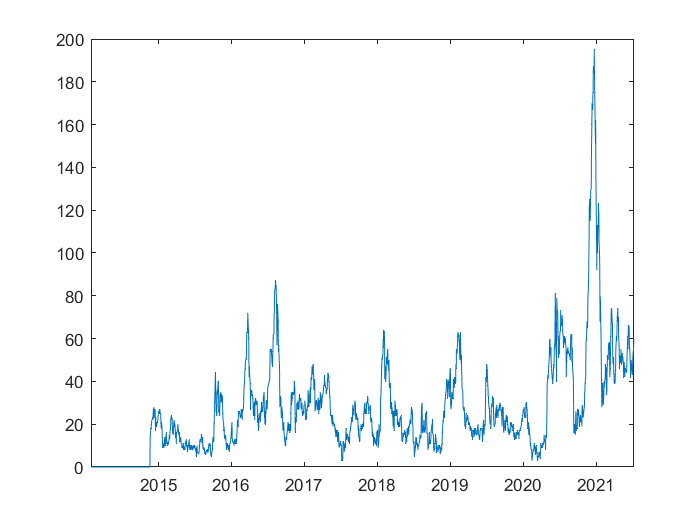

summaryTable = 9×1 table
                       TrendTradeStrategy
                       __________________

    TotalReturn               3.7425     
    SharpeRatio             0.074668     
    Volatility              0.013852     
    AverageTurnover          0.10194     
    MaxTurnover              0.77778     
    AverageReturn           0.001034     
    MaxDrawdown              0.47172     
    AverageBuyCost            38.453     
    AverageSellCost           51.151     


EndCumSumVar = -4.7425

TradingPeriod = 6.6384

CAGR = -0.2643

SharpeRatio = -1.1806

Sortino = -1.7552

Elapsed time is 19.509631 seconds.


SharpeRatio = -1.1806

% x = [10^3	10^9	100	80	200	10^15	10^15	200	80	200	200	80	200]

% lb = [10^3	10^6	1	-50	1	1	1	1	-50	1	1	-50	2] ;
% ub = [10^15	10^15	200	80	200	10^15	10^15	200	80	200	200	80	200] ;

% LowSkipValTreshCorrection = x(1) ; 
% MinValue = x(2) ;
% MomContDays = x(3) ; 
% MomContRetTrheshold = x(4) ; 
% LowLiquidDays = x(5) ;
% LowLiquidThreshold = x(6) ;
% LiquidSurgThreshold = x(7) ; % in %
% MomMainDays = x(8) ;
% MomMainRetThreshold = x(9) ;
% PostSignalBufferDays = x(10) ;
% StopLossLookbackWindSz = x(11) ;
% StopLossThreshold = x(12) ;
% RebalanceFreq = x(13) ;

% Call the function
SharpeRatio = TrendTradingFcnMultiVarSharpe (x, PricesIST, VolumesIST) 

Optimize parameters in IST by using Genetic Algo

options = optimoptions ('ga', 'UseParallel', true, 'UseVectorized', ...
    false, "FunctionTolerance", 0.05, "MaxGenerations",20, 'MaxTime', 60*5)

options =   ga options:

   Set properties:
               FunctionTolerance: 0.05
                  MaxGenerations: 20.00
                         MaxTime: 300.00
                     UseParallel: 1
                   UseVectorized: 0

   Default properties:
             ConstraintTolerance: 0.00
                     CreationFcn: @gacreationuniform
                    CrossoverFcn: @crossoverscattered
               CrossoverFraction: 0.80
                         Display: 'final'
                      EliteCount: '0.05*PopulationSize'
                    FitnessLimit: -Inf
               FitnessScalingFcn: @fitscalingrank
                       HybridFcn: []
         InitialPopulationMatrix: []
          InitialPopulationRange: []
             InitialScoresMatrix: []
             MaxStallGenerations: 50.00
                    MaxStallTime: Inf
                     MutationFcn: {@mutationgaus

options = optimoptions(options,'PlotFcn',{@gaplotbestf,@gaplotstopping})

options =   ga options:

   Set properties:
               FunctionTolerance: 0.05
                  MaxGenerations: 20.00
                         MaxTime: 300.00
                         PlotFcn: {@gaplotbestf  @gaplotstopping}
                     UseParallel: 1
                   UseVectorized: 0

   Default properties:
             ConstraintTolerance: 0.00
                     CreationFcn: @gacreationuniform
                    CrossoverFcn: @crossoverscattered
               CrossoverFraction: 0.80
                         Display: 'final'
                      EliteCount: '0.05*PopulationSize'
                    FitnessLimit: -Inf
               FitnessScalingFcn: @fitscalingrank
                       HybridFcn: []
         InitialPopulationMatrix: []
          InitialPopulationRange: []
             InitialScoresMatrix: []
             MaxStallGenerations: 50.00
                    


FitnessFunction = @(x) TrendTradingFcnMultiVarSharpe (x, PricesIST, VolumesIST) ;
nvars = 13 ;
lb = [1	1	1	-20	1	1	1	1	-20	1	1	-10	1] ;
ub = [10^15	10^15	200	80	200	10^15	10^15	200	80	200	200	80	50] ;

% ConstraintFunction = @nlconGA ;
IntCon = 1:nvars ;

[x, fval] = ga(FitnessFunction, nvars, [], [], [], [], lb, ub, [],IntCon, options )


summaryTable =

  9x1 table

                       TrendTradeStrategy
                       __________________

    TotalReturn                 0        
    SharpeRatio               NaN        
    Volatility                  0        
    AverageTurnover             0        
    MaxTurnover                 0        
    AverageReturn               0        
    MaxDrawdown                 0        
    AverageBuyCost              0        
    AverageSellCost             0        


EndCumSumVar =

    -1


TradingPeriod =

    8.3973


CAGR =

     0


SharpeRatio =

     0

Elapsed time is 28.664355 seconds.

summaryTable =

  9x1 table

                       TrendTradeStrategy
                       __________________

    TotalReturn                 0        
    SharpeRatio               NaN        
    Volatility                  0        
    AverageTurnover             0        
    MaxTurnover                 0        
    AverageReturn               0        
    MaxD


summaryTable =

  9x1 table

                       TrendTradeStrategy
                       __________________

    TotalReturn                 0        
    SharpeRatio               NaN        
    Volatility                  0        
    AverageTurnover             0        
    MaxTurnover                 0        
    AverageReturn               0        
    MaxDrawdown                 0        
    AverageBuyCost              0        
    AverageSellCost             0        


EndCumSumVar =

    -1


TradingPeriod =

    8.3973


CAGR =

     0


SharpeRatio =

     0


Sortino =

   NaN

Elapsed time is 29.127437 seconds.

summaryTable =

  9x1 table

                       TrendTradeStrategy
                       __________________

    TotalReturn                 0        
    SharpeRatio               NaN        
    Volatility                  0        
    AverageTurnover             0        
    MaxTurnover                 0        
    AverageReturn             


xSharpeGAOptimized = x ;


Optimize Sharpe Ratio by using Surrogate optim Algo

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 4).


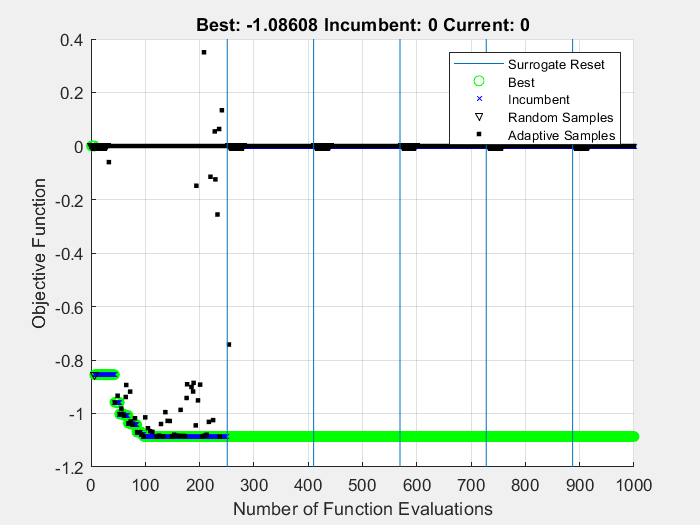

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


%surrogateopt for expensive optim problems

NumFunctionEvaluations = 1000 ;
options = optimoptions('surrogateopt','PlotFcn',"surrogateoptplot", ...
    "ConstraintTolerance",1e-6,'MaxFunctionEvaluations',NumFunctionEvaluations, 'UseParallel', true);

fun = @(x) TrendTradingFcnMultiVarSharpe (x, PricesIST, VolumesIST) ;
nvar = 13 ;
lb = [10^3	10^6	1	-20	1	1	1	1	-20	1	1	-20	1] ;
ub = [10^12	10^12	200	80	200	10^8	10^12	200	80	200	200	80	50] ;
intcon = 1:nvar ;

[xSharpeSur,fvalm,~,~,pop] = surrogateopt(fun,lb,ub,intcon,options);


xSharpeSurOptimized = xSharpeSur 

xSharpeSurOptimized =         1000     1000000          26          -7           1           1           1          14         -20          76           1         -20          28



xOptimizedsave = [xOptimized; xSharpeSur]

xOptimizedsave =            1           1          17         -50           1           1           1           1         -50           8           1         -50           1
        1000     1000000          26          -7           1           1           1          14         -20          76           1         -20          28


Optimize Sortino Ratio by using surrogateopt

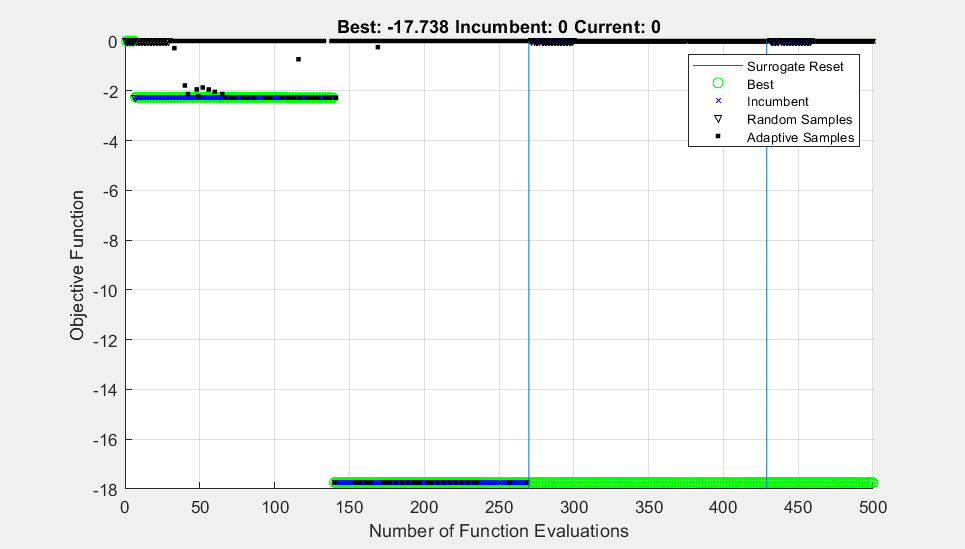

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


%surrogateopt for expensive optim problems

options = optimoptions('surrogateopt','PlotFcn',"surrogateoptplot", ...
    "ConstraintTolerance",1e-6,'MaxFunctionEvaluations',500, 'UseParallel', true);

fun = @(x) TrendTradingFcnMultiVarSortino (x, PricesIST, VolumesIST) ;
nvars = 13 ;
lb = [1	1	1	-50	1	1	1	1	-50	1	1	-50	1] ;
ub = [10^15	10^15	200	80	200	10^15	10^15	200	80	200	200	80	100] ;
intcon = 1:nvars ;

[xSortinoSur,fvalm,~,~,pop] = surrogateopt(fun,lb,ub,intcon,options);


xSortinoSurOptimized = xSortinoSur ;



Optimize CumsumEnd by using surrogateopt

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 4).


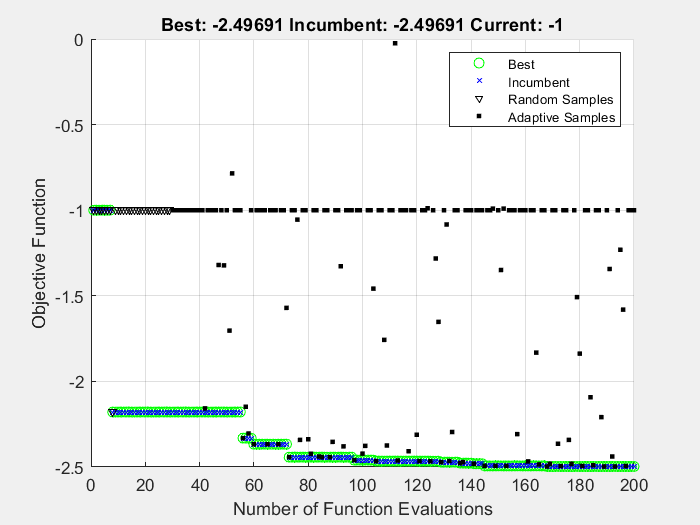

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


xCumsumEndSur =         1000     1000000          20         -20           5           1           1           1         -18          27           1         -20          12


fvalm = -2.4969

pop = struct with fields:
       X: [200×13 double]
    Fval: [200×1 double]


%surrogateopt for expensive optim problems

NumFunctionEvaluations = 200 ;
options = optimoptions('surrogateopt','PlotFcn',"surrogateoptplot", ...
    "ConstraintTolerance",1e-6,'MaxFunctionEvaluations',NumFunctionEvaluations, 'UseParallel', true);

fun = @(x) TrendTradingFcnMultiVarCumsumEnd (x, PricesIST, VolumesIST) ;
nvar = 13 ;
lb = [10^3	10^6	1	-20	1	1	1	1	-20	1	1	-20	1] ;
ub = [10^12	10^12	200	80	200	10^8	10^12	200	80	200	200	80	50] ;
intcon = 1:nvar ;

[xCumsumEndSur,fvalm,~,~,pop] = surrogateopt(fun,lb,ub,intcon,options)


xCumsumEndSurOptimized = xCumsumEndSur 

xCumsumEndSurOptimized =         1000     1000000          20         -20           5           1           1           1         -18          27           1         -20          12



xOptimizedsave = [xOptimized; xCumsumEndSurOptimized]

xOptimizedsave =         1000     1000000          26          -7           1           1           1          14         -20          76           1         -20          28
        1000     1000000          20         -20           5           1           1           1         -18          27           1         -20          12


Pareto Search Multi-Objective Optim Sharpe Sortino CAGR

summaryTable = 9×1 table
                       TrendTradeStrategy
                       __________________

    TotalReturn                 0        
    SharpeRatio               NaN        
    Volatility                  0        
    AverageTurnover             0        
    MaxTurnover                 0        
    AverageReturn               0        
    MaxDrawdown                 0        
    AverageBuyCost              0        
    AverageSellCost             0        


EndCumSumVar = -1

TradingPeriod = 8.3973

CAGR = 0

SharpeRatio = 0

Sortino = NaN

Elapsed time is 12.336697 seconds.


summaryTable = 9×1 table
                       TrendTradeStrategy
                       __________________

    TotalReturn                 0        
    SharpeRatio               NaN        
    Volatility                  0        
    AverageTurnover             0        
    MaxTurnover                 0        
    AverageReturn               0        
    MaxDrawdown                 0        
    AverageBuyCost              0        
    AverageSellCost             0        


EndCumSumVar = -1

TradingPeriod = 8.3973

CAGR = 0

SortinoRatio = 0

Elapsed time is 12.500830 seconds.


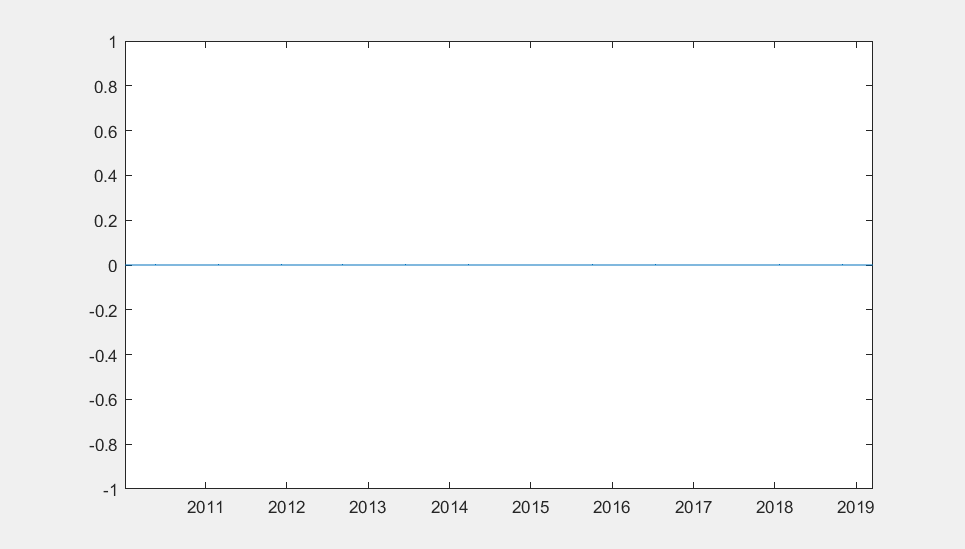

summaryTable = 9×1 table
                       TrendTradeStrategy
                       __________________

    TotalReturn                 0        
    SharpeRatio               NaN        
    Volatility                  0        
    AverageTurnover             0        
    MaxTurnover                 0        
    AverageReturn               0        
    MaxDrawdown                 0        
    AverageBuyCost              0        
    AverageSellCost             0        


EndCumSumVar = -1

TradingPeriod = 8.3973

CAGR = 0

SharpeRatio = NaN

SortinoRatio = NaN

Elapsed time is 13.045303 seconds.


Unrecognized function or variable 'isna'.

Error in SharpeSortinoCAGRFitFcn (line 6)
SharpeRatio (isna (SharpeRatio)) = 0 ;

Error in TrendTradingMainScript (line 102)
fun = @(x) SharpeSortinoCAGRFitFcn (x, PricesIST, VolumesIST) ;

Error in 

optsp = optimoptions('paretosearch','UseParallel', true,'PlotFcn',{'psplotparetof' 'psplotparetox'});
fun = @(x) SharpeSortinoCAGRFitFcn (x, PricesIST, VolumesIST) ;
nvars = 13 ;
lb = [1	1	1	-50	1	1	1	1	-50	1	1	-50	1] ;
ub = [10^15	10^15	200	80	200	10^15	10^15	200	80	200	200	80	100] ;
intcon = 1:nvar ;

% [xSsharpeSorCAGRPareto,fvalp,~,psoutput] = paretosearch(fun,nvars,[],[],[],[],[],[],[],optsp)
% [xSsharpeSorCAGRPareto,fvalp,~,psoutput] = paretosearch(fun,nvars,[],[],[],[],[],[],[],optsp);
[xSharpeSorCAGRPareto,fvalp,~,psoutput] = paretosearch(fun, nvars, [], [], [], [], lb, ub, [], optsp)


xSharpeSorCAGRParetoOptimized = xSharpeSorCAGRPareto ;

Genetic Algo Multi-Objective Optim Sharpe Sortino CAGR

summaryTable = 9×1 table
                       TrendTradeStrategy
                       __________________

    TotalReturn                 0        
    SharpeRatio               NaN        
    Volatility                  0        
    AverageTurnover             0        
    MaxTurnover                 0        
    AverageReturn               0        
    MaxDrawdown                 0        
    AverageBuyCost              0        
    AverageSellCost             0        


EndCumSumVar = -1

TradingPeriod = 8.3973

CAGR = 0

SharpeRatio = 0

Sortino = NaN

Elapsed time is 25.856827 seconds.


summaryTable = 9×1 table
                       TrendTradeStrategy
                       __________________

    TotalReturn                 0        
    SharpeRatio               NaN        
    Volatility                  0        
    AverageTurnover             0        
    MaxTurnover                 0        
    AverageReturn               0        
    MaxDrawdown                 0        
    AverageBuyCost              0        
    AverageSellCost             0        


EndCumSumVar = -1

TradingPeriod = 8.3973

CAGR = 0

SortinoRatio = 0

Elapsed time is 26.548901 seconds.


summaryTable = 9×1 table
                       TrendTradeStrategy
                       __________________

    TotalReturn                 0        
    SharpeRatio               NaN        
    Volatility                  0        
    AverageTurnover             0        
    MaxTurnover                 0        
    AverageReturn               0        
    MaxDrawdown                 0        
    AverageBuyCost              0        
    AverageSellCost             0        


EndCumSumVar = -1

TradingPeriod = 8.3973

CAGR = 0

SharpeRatio = NaN

SortinoRatio = NaN

Elapsed time is 26.798486 seconds.


Unrecognized function or variable 'isna'.

Error in SharpeSortinoCAGRFitFcn (line 6)
SharpeRatio (isna (SharpeRatio)) = 0 ;

Error in TrendTradingMainScript (line 114)
fun = @(x) SharpeSortinoCAGRFitFcn (x, PricesIST, VolumesIST) ;

Error in 

options = optimoptions(@gamultiobj, 'PlotFcn',@gaplotpareto, 'UseParallel', true);
fun = @(x) SharpeSortinoCAGRFitFcn (x, PricesIST, VolumesIST) ;
nvars = 13 ;
lb = [1	1	1	-50	1	1	1	1	-50	1	1	-50	1] ;
ub = [10^15	10^15	200	80	200	10^15	10^15	200	80	200	200	80	100] ;
intcon = 1:nvars ;

% [xSharpeSorCAGRPareto,fvalp,~,psoutput] = paretosearch(fun,nvars,[],[],[],[],[],[],[],intcon,optsp)
% [xSharpeSorCAGRPareto,fvalp,~,psoutput] = paretosearch(fun,nvars,[],[],[],[],[],[],[],optsp);
[xSharpeSorCAGRgamultiobj ,Fval,exitFlag,Output] = gamultiobj(fun, nvars, [], [], [], [], lb, ub, [], options)


xSharpeSorCAGRgamultiobjOptimized = xSharpeSorCAGRgamultiobj ;

Apply the parameters into IST - OST

% xOptimized = xGAOptimized;
xOptimized = xSharpeSurOptimized ;
% xOptimized =  xSortinoSurOptimized ;
xOptimized = xCumsumEndSurOptimized

xOptimized =         1000     1000000          20         -20           5           1           1           1         -18          27           1         -20          12


summaryTable = 9×1 table
                       TrendTradeStrategy
                       __________________

    TotalReturn                1.4969    
    SharpeRatio              0.069109    
    Volatility               0.006433    
    AverageTurnover         0.0078133    
    MaxTurnover                   0.5    
    AverageReturn          0.00044447    
    MaxDrawdown               0.36272    
    AverageBuyCost             1.8387    
    AverageSellCost             2.359    


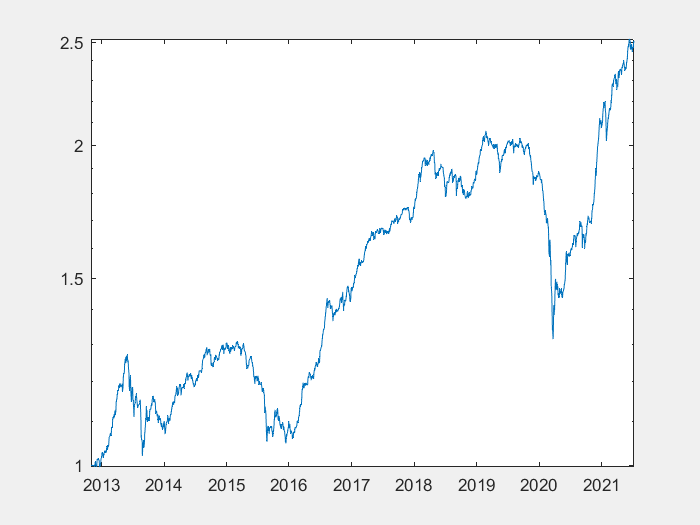

EndCumSumVar = -2.4969

TradingPeriod = 8.6932

CAGR = -0.1110

SharpeRatio = -1.0927

SortinoRatio = 1.2901

MaxDD = 0.3627

StartEndMaxDD = 2×1 datetime array
   25-Feb-2019
   23-Mar-2020


Elapsed time is 18.655134 seconds.


SharpeRatioOptimized = -1.0927


SharpeRatioOptimized = TrendTradingFcnMultiVarSharpeGraph (xOptimized, PricesIST, VolumesIST) 

SharpeRatioOptimized = TrendTradingFcnMultiVarSharpeGraph (xOptimized, PricesOST, VolumesOST)

Error using TrendTradingFcnMultiVarSharpeGraph (line 105)
To assign to or create a variable in a table, the number of rows must match the height of the table.

SharpeRatioOptimized = TrendTradingFcnMultiVarSharpeGraph (xOptimized, PricesTTFull, VolumesTTFull)

Examine OST

Save Variable


save ("TrendTrading.mat", 'PricesTTFull', "VolumesTTFull",  "xSharpeSurOptimized", ...
    'xSortinoSurOptimized', 'xOptimized', 'xOptimizedsave') 

Closing

toc

Elapsed time is 277.053214 seconds.
